# Setting Assumptions

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code defines and plots the expression `expr`.

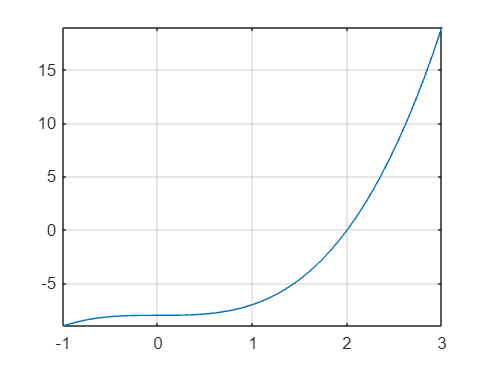

syms x
y = x^3 - 8;
fplot(y,[-1 3])
grid on

## Task 1

In the script, the expression 

x^3−8 is plotted. To find where the line crosses the x-axis, you can create  an equation which sets the expression equal to 0, and then solve.

Task

Set `y` equal to 0 and store the equation as `eqn`. Then solve `eqn` for `x` and store the result as `sol`.

eqn=y==0

$$eqn = x^{3}-8=0$$

sol=solve(eqn,x)

$$sol = \left(\begin{array}{c} 2\\ -1-\sqrt{3}\,\mathrm{i}\\ -1+\sqrt{3}\,\mathrm{i} \end{array}\right)$$

## Task 2

In the plot, you can see the line only crosses the x-axis at one location, but `sol` contains three solutions: one real solution and two complex solutions.

The `assume` function lets you place assumptions on symbolic variables so they only  take on values from a particular set, like the real numbers. 

For example, you can assume the variable `a` is an integer.

`assume``(``a``,``'integer'``)`

Task

Assume that `x` is `'real'`.

assume(x,"real")

## Task 3

Assumptions aren't displayed, so to see all the existing assumptions on a variable, use the `assumptions` function.

`zAsmp` `=` `assumptions``(``z``)`

Task

Find all the assumptions on `x` and store them in the variable `check`.

check=assumptions(x)

$$check = x\in \mathbb{R}$$

## Task 4

Assumptions are used by the function `solve` to restrict the returned solutions. Now that `x` can only be a real number, that information will be used when solving for `x`.

Task

Solve `eqn` for `x` again. Store the result as `realsol`.

realsol=solve(eqn,x)

$$realsol = 2$$

## Task 5

You should clear the assumptions on a variable when you no longer need them.

`assume``(``var``,``'clear'``)`

Because assumptions aren't displayed unless you use the `assumptions` function, uncleared assumptions could inadvertently impact future computations.

Task

Clear the assumptions on the variable `x`.

assume(x,"clear")

## Further Practice

You can also place assumptions on expressions. For example, you can assume `x` is even by assuming `x``/``2` is an integer.

`assume``(``x``/``2``,``'integer'``)`

Assumptions can be stated using relational operators, like `>`, `<`, `>=`, etc. To assume `x` is greater than 5, use

`assume``(``x` `>` `5``)`

Other functions also use assumptions when determining results. For example, try simplifying the expression 

√z2. Then assume `z` is nonnegative and simplify the expression again.

`syms` `z`

`simplify``(``sqrt``(``z``^``2``))`

`assume``(``z` `>=` `0``)`

`simplify``(``sqrt``(``z``^``2``))`

Remember to clear assumptions when you're finished using them.

assume(z,'clear')
assume(x/2,"integer")
assumptions(x/2)

$$ans = \frac{x}{2}\in \mathbb{Z}$$

assume(x>5)
assumptions(x)

$$ans = 5<x$$

syms z
simplify(sqrt(z^2))

$$ans = \sqrt{z^{2}}$$

assume(z>0)
simplify(sqrt(z^2))

$$ans = z$$

assume(z,"clear")